% %Sinusoidal signal
% 
% n=-1:0.01:1;
% A=2;
% f0=2.4;
% omega=2*pi*f0;
% phi=60*pi/180;
% cos_t=A*cos(omega*n+phi);
% sin_t=A*sin(omega*n+phi);
% plot(n,cos_t)
% hold on
% plot(n,sin_t)
% grid;
% hold off
% xlabel('Time(t)');
% ylabel('x(t)');
% title('Sinusoidal Signal');
% legend('Acos(\omegat+\phi)','Asin(\omegat+\phi))')


% %Sinc function
% 
% n=-4*pi:pi/360:4*pi;
% for c=1:length(n)
%     sinc_t(1,c)=sin(pi*n(1,c))/(pi*n(1,c));
% end
% plot(n,sinc_t);
% xlim([-4*pi 4*pi]);
% ylim([-0.3 1.2]);
% grid
% xlabel('Time(t)');
% ylabel('x(t)');
% title('Sinc Signal:sin(\pit)/\pit');

% %Discrete-time signal
% 
% N=21; A=1; omega=0.5; theta=2; 
% n=0:N-1;
% 
% cos_n=A*cos(omega*n+theta);
% sin_n=A*sin(omega*n+theta);
% 
% subplot(2,1,1); stem(n,cos_n);
% xlabel('Time[n]')
% ylabel('x_[n]')
% title('Sinusoidal Signal:Acos(\omegan+\theta)');
% legend('Acos(\omegan+\theta)')
% subplot(2,1,2); stem(n,sin_n);
% grid
% xlabel('Time[n]')
% ylabel('x_[n]')
% title('Sinusoidal Signal:Asin(\omegan+\theta)');
% legend('Asin(\omegan+\theta))')

% %Unit-step function
% 
% n=-5:1:5;
% u_n(n<0)=0
% u_n(n>=0)=1
% x_n(n<2)=0
% x_n(n>=2)=1
% subplot(2,1,1); stem(n,u_n);
% axis([-5 5 -0.5 1.5]);
% grid
% xlabel('Time[n]');
% ylabel('u[n]')
% title('Unit Step Signal:u[n]')
% subplot(2,1,2); stem(n,x_n);
% axis([-5 5 -0.5 1.5]);
% grid
% xlabel('Time[n]');
% ylabel('u[n-2]')
% title('Unit Step Signal:u[n-2]')

% %Impulse function
% 
% n=-5:1:5;
% x_n=dirac(n);
% x_n(find(x_n==inf))=1;
% stem(n,x_n)
% axis([-5 5 -0.5 1.5])
% grid
% xlabel('Time[n]');
% ylabel('x[n]')
% title('Impulse Signal:\delta[n]')

% %Continouous-time convolution
% 
% 
% dt=0.01;
% t=-6:dt:6;
% 
% %u_t=u(t)
% u_t(t<0)=0;
% u_t(t>=0)=1;
% 
% %u_t1=u(t-1)
% u_t1(t>=1)=1;
% u_t1(t<1)=0;
% 
% %u_t_1=u(t+1)
% u_t_1(t<-1)=0;
% u_t_1(t>=-1)=1;
% 
% %u_t2=u(t-2)
% u_t2(t<2)=0;
% u_t2(t>=2)=1;
% 
% x_t=u_t_1-u_t1;
% h_t=(-t+2).*(u_t-u_t2);
% flip_h_t=flip(h_t);
% flip_h_t0=circshift(flip_h_t,find(t==0));
% for c=1:length(t)
%     y_t(1,c)=sum(x_t.*circshift(flip_h_t0,c))*dt;
% end
% subplot(3,1,1); plot(t,x_t);
% axis([-6 6 0 3]);
% grid;
% xlabel('Time(t)');
% ylabel('x(t)');
% title('Input Signal')
% subplot(3,1,2); plot(t,h_t);
% axis([-6 6 0 3]);
% grid;
% xlabel('Time(t)');
% ylabel('h(t)');
% title('Impulse Response Signal')
% subplot(3,1,3); plot(t,y_t);
% axis([-6 6 0 3]);
% grid;
% xlabel('Time(t)');
% ylabel('y(t)');
% title('Output Signal')

% %Discrete-time convolution
% 
% 
% dt=1;
% n=-6:dt:6;
% 
% %u_t=u[n]
% u_n(n<0)=0;
% u_n(n>=0)=1;
% 
% %u_t1=u[n-1]
% u_n1(n<1)=0;
% u_n1(n>=1)=1;
% 
% %u_t_1=u[n+1]
% u_n_1(n<-1)=0;
% u_n_1(n>=-1)=1;
% 
% 
% %u_t2=u[n-2]
% u_n2(n>=2)=1;
% u_n2(n<2)=0;
% 
% 
% x_n=u_n_1-u_n1;
% h_n=(-n+2).*(u_n-u_n2);
% flip_h_n=flip(h_n);
% flip_h_n0=circshift(flip_h_n,find(n==0));
% for c=1:length(n)
%     y_n(1,c)=sum(x_n.*circshift(flip_h_n0,c-1))*dt;
% end
% subplot(3,1,1); plot(n,x_n);
% axis([-6 6 0 5]);
% grid;
% xlabel('Time(t)');
% ylabel('x(t)');
% title('Input Signal')
% subplot(3,1,2); plot(n,h_n);
% axis([-6 6 0 5]);
% grid;
% xlabel('Time(t)');
% ylabel('h(t)');
% title('Impulse Response Signal')
% subplot(3,1,3); plot(n,y_n);
% axis([-6 6 0 5]);
% grid;
% xlabel('Time(t)');
% ylabel('y(t)');
% title('Output Signal')

% %Continuous-time Fourier transform
% 
% dt=1/100; tmax=4;
% t=0:dt:tmax;
% x_t=cos(2*pi*t);
% X_f=fft(x_t);
% N=length(x_t);
% X_spec=abs(X_f)/N;
% freq=(0:N-1);
% subplot(2,1,1); plot(t,x_t);
% grid;
% axis([0 tmax -2 2]);
% xlabel('Time(t)');
% ylabel('x(t)');
% subplot(2,1,2); plot(freq,X_spec);
% grid;
% xlabel('Frequency (Hz)');
% ylabel('X(f)');

% %Continuous-time Fourier transform
% 
% T=2; N=512; Ts=T/N;
% t=Ts*(0:(N-1));
% phi1=pi/3; phi2=pi/2;
% x_t=cos(5*pi*t-phi1)+3*cos(8*pi*t-phi2);
% X_f=fft(x_t);
% X_amp=abs(X_f)/N;
% X_phase=angle(X_f);
% k=0:30;
% subplot(2,1,1); stem(k,X_amp(1:length(k)));
% grid;
% xlabel('k');
% ylabel('|X(f)|');
% title('Amplitude Spectrum');
% subplot(2,1,2); stem(k,X_phase(1:length(k)));
% grid;
% xlabel('k');
% ylabel('\angleX(f)');
% title('Phase Spectrum');

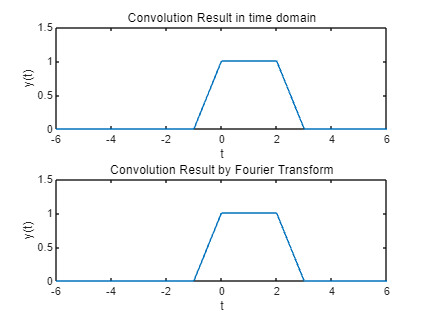

% %Continuous-time Fourier transform
% 
% tmin=-6; tmax=6; N=5000;
% dt=(tmax-tmin)/N;
% t=tmin:dt:tmax;
% x_t=stepfun(t,-1)-stepfun(t,2);
% h_t=stepfun(t,0)-stepfun(t,1);
% y_t=conv(x_t,h_t)*dt;
% X_f=dt*fft(x_t);
% H_f=dt*fft(h_t);
% Y_f=X_f.*H_f;
% y_ft=fftshift((1/dt)*ifft(Y_f));
% subplot(2,1,1); plot(t,y_t(2501:7501));
% axis([-6 6 0 1.5]);
% xlabel('t');
% ylabel('y(t)');
% title('Convolution Result in time domain');
% subplot(2,1,2); plot(t,y_ft);
% axis([-6 6 0 1.5]);
% xlabel('t');
% ylabel('y(t)');
% title('Convolution Result by Fourier Transform')

% %Discrete-time Fourier series
% 
% N=8; 
% x_n=[1 1 1 1 1 0 0 0];
% omega0=2*pi/N;
% n=-N/2+1:N/2;
% w_N=exp(-1j*omega0*n);
% for k=1:N
%     a_k(k)=sum(x_n.*w_N.^(k-1)/N);
% end 
% a_k;
% a_mag=abs(a_k);
% a_phase=angle(a_k);
% k=0:N-1;
% subplot(2,1,1); stem(k,a_mag);
% xlabel('k');
% ylabel('\bf{|a_k|}');
% title('Magnitude Response');
% subplot(2,1,2); stem(k,a_phase);
% xlabel('k');
% ylabel('\bf{\anglea_k}');
% title('Phase Response')

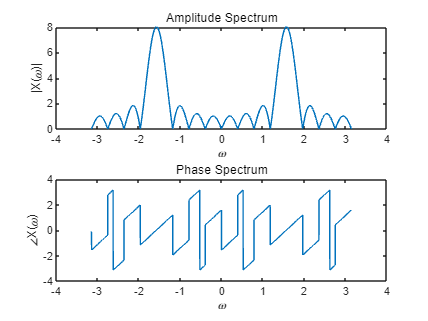

%Discrete-time Fourier transform

n=-10:5;
omega=-pi:1/500:pi;
x_n=cos(3*pi*n/2);
X_f=x_n*(exp(-j*n'*omega));
X_spec=abs(X_f);
X_phase=angle(X_f);
subplot(2,1,1); plot(omega,X_spec);
xlabel('\omega');
ylabel('|X(\omega)|');
title('Amplitude Spectrum');
subplot(2,1,2); plot(omega,X_phase);
xlabel('\omega');
ylabel('\angleX(\omega)');
title('Phase Spectrum');